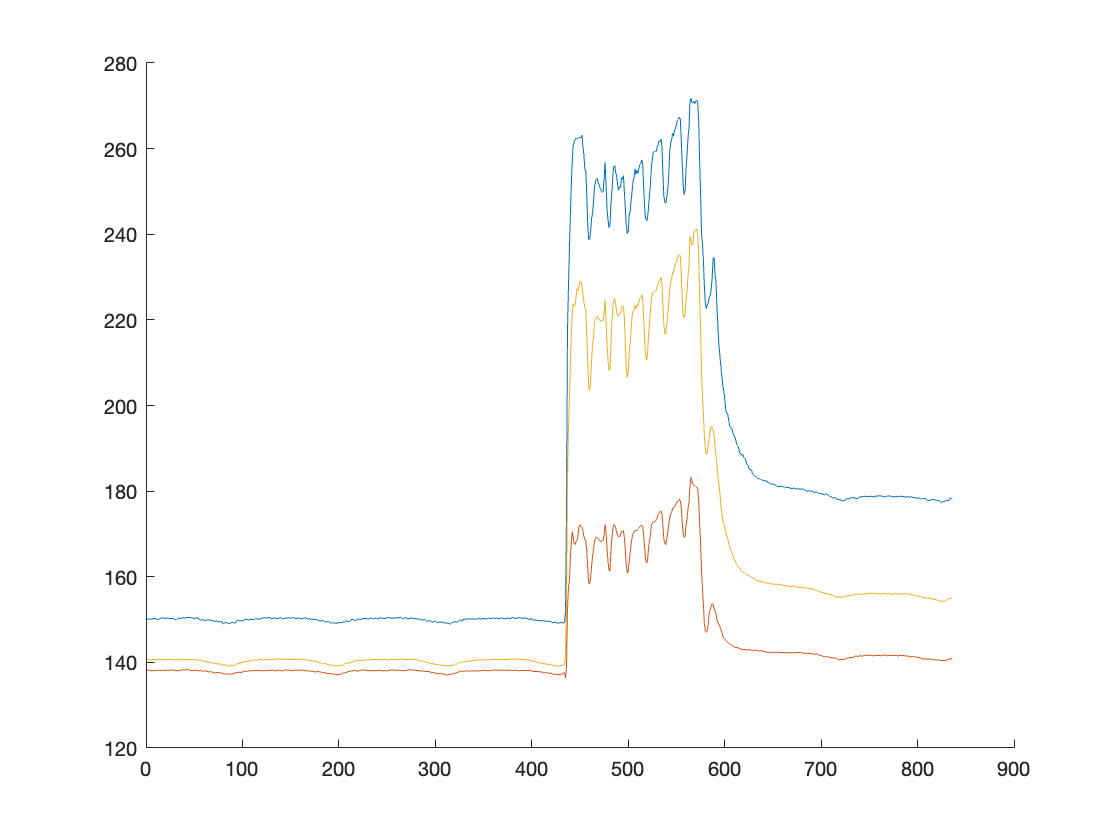

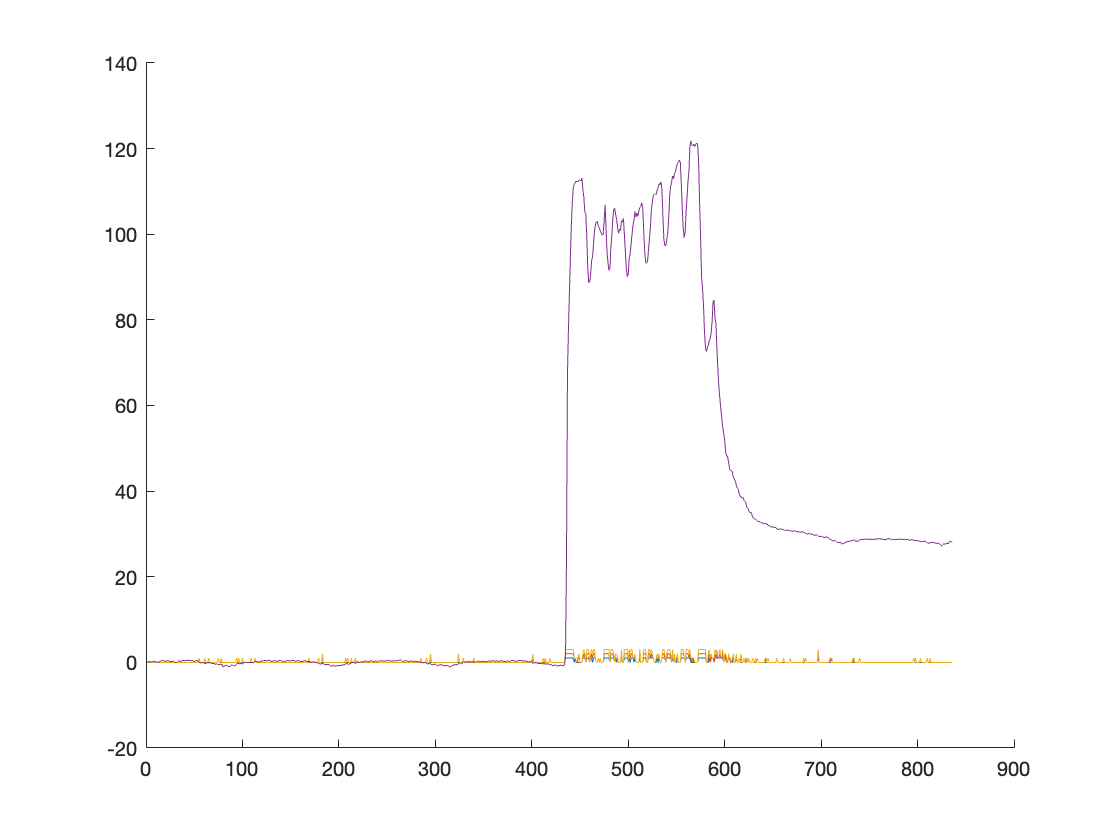

figure

hold on
plot(normalizedData.toe.X);
plot(normalizedData.ankle.X);
plot(normalizedData.MTP.X);
hold off

figure
hold on
a = ischange(normalizedData.toe.X);
b = ischange(normalizedData.ankle.X) + a;
c = ischange(normalizedData.MTP.X) + b;
plot(a);
plot(b);
plot(c);
plot(normalizedData.toe.X - 150);
hold off

csvPath = {'/Users/sam/OneDrive - Northwestern University/Documents/Data/Rat/SCI tests/J2/09102021J2/cam1_C7SAMP50_2021-09-10_1DLC_resnet101_Spinal ImplantOct5shuffle1_1868000.csv'}    

csvPath = 1×1 cell array
    {'/Users/sam/OneDrive - Northwestern University/Documents/Data/Rat/SCI tests/J2/09102021J2/cam1_C7SAMP50_2021-09-10_1DLC_resnet101_Spinal ImplantOct5shuffle1_1868000.csv'}


resolutionHead = {'capture-frames', 'video-data.csv'};
    if ispc
        splitter = "\";
    elseif ismac
        splitter = "/";
    end
    resolutionHead = join(resolutionHead, splitter);
    partSplit = split(csvPath, splitter);
    fileName = partSplit(end);
    partName = split(fileName, '_');
    recordingName = partName(1:3);
    recordingName = cell2mat(join(recordingName, '_'));
sampleName = partName(1:2);
sampleName = cell2mat(join(sampleName, '_'));
sampleDate = partName(3);